% Build a simple 2-muscle 2D arm
l_0 = 0.5;
rho = 0.0254;
N_segments = 3;

arm_series_2d = ArmSeriesFactory.constant_2d_muscle_arm(N_segments, rho, l_0);
arm_series_2d.set_mechanics(GinaMuscleMechanics(l_0));
arm_segment_2d = arm_series_2d.segments(1);

Q = [0; -2; 0];
pressures = [30; 0];

%% First solve the scenario with Gina's model
g_circ_right_eq_gina = arm_series_2d.solve_equilibrium_gina(pressures, Q)


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


g_circ_right_eq_gina =     0.4761    0.4777    0.4823
   -0.0000   -0.0000    0.0000
   -0.1058   -0.2012   -0.5180


g_ucirc_left_gina = -arm_series_2d.calc_external_reaction(Q)

g_ucirc_left_gina =    -2.0000   -1.9988   -1.9895
         0   -0.0705   -0.2043
   -0.0877   -0.0821   -0.0602


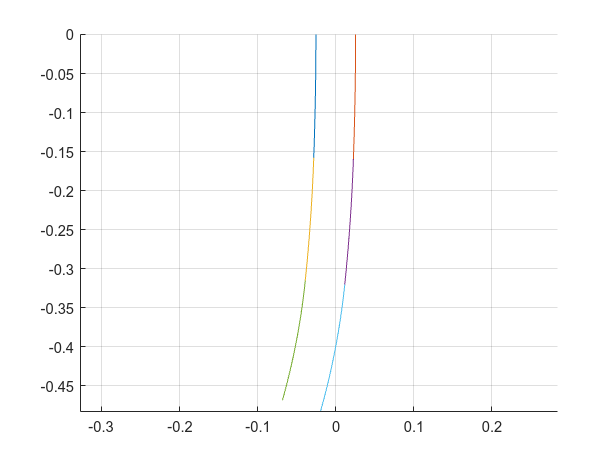

Plotter2D.plot_arm_series(arm_series_2d, axes(figure()))

%% Check: Can we correctly solve for tg_circ_right of the first segment?
seg = arm_series_2d.segments(1);
f_segment_residual = @(g_circ_right) seg.mat_A * seg.get_forces(pressures, g_circ_right) - g_ucirc_left_gina(:, 1);

% verify that the cost function works
gina_soln = g_circ_right_eq_gina(:, 1)

gina_soln =     0.4761
   -0.0000
   -0.1058


gina_residual = f_segment_residual(g_circ_right_eq_gina(:, 1))

gina_residual = 1.0e-07 *

    0.0001
         0
    0.1371



% Directly solve for the g_circ_right where the residual is zero:
% Solve using the three different fsolve algorithms to compare them
opt_lm = optimoptions("fsolve", "Algorithm", "levenberg-marquardt");
opt_tr = optimoptions("fsolve", "Algorithm", "trust-region");
opt_dl = optimoptions("fsolve", "Algorithm", "trust-region-dogleg");

[soln_lm, residual_lm] = fsolve(f_segment_residual, [0.5; 0; 0], opt_lm)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


soln_lm =     0.4761
         0
   -0.1058


residual_lm = 1.0e-13 *

   -0.3419
         0
    0.7165


[soln_tr, residual_tr] = fsolve(f_segment_residual, [0.5; 0; 0], opt_tr);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[soln_dl, residual_dl] = fsolve(f_segment_residual, [0.5; 0; 0], opt_dl);


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+02.



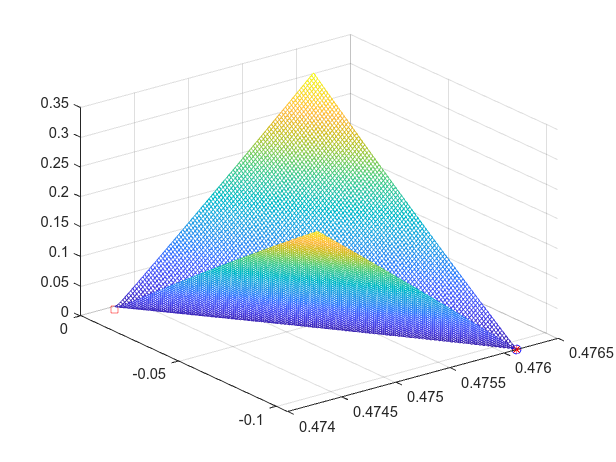

solns = [gina_soln, soln_lm, soln_tr, soln_dl];
[ls_min, ls_max] = bounds(solns(1, :));
[ks_min, ks_max] = bounds(solns(3, :));

% Plot the residual landscape around the solution that we've arrived at
n_points = 100;
ls = linspace(ls_min, ls_max, n_points);
ks = linspace(ks_min, ks_max, n_points);
[Ls, Ks] = meshgrid(ls, ks);
Fs = zeros(n_points, n_points);
for i = 1 : n_points
    for j = 1 : n_points
        Fs(i, j) = norm(f_segment_residual([Ls(i, j); 0; Ks(i, j)]));
    end
end

figure()
mesh(Ls, Ks, Fs)
hold on
scatter3(g_circ_right_eq_gina(1, 1), g_circ_right_eq_gina(3, 1), norm(gina_residual), 'bo');
scatter3(soln_lm(1, 1), soln_lm(3, 1), norm(residual), "rx")
scatter3(soln_tr(1, 1), soln_tr(3, 1), norm(residual), "r+")
scatter3(soln_dl(1, 1), soln_dl(3, 1), norm(residual), "rsquare")

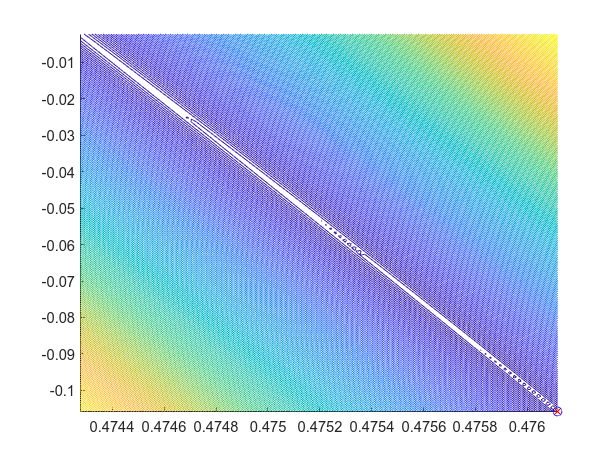

figure()
hold on
contour(Ls, Ks, Fs, 200);
plot(g_circ_right_eq_gina(1, 1), g_circ_right_eq_gina(3, 1), "bo");
plot(soln(1, 1), soln(3, 1), "rx");

%% Check: Can we correctly forward integrate a strain in the base
g_ucirc_left_0_guess = g_ucirc_left_gina(:, 1);
g_0 = arm_series_2d.segments(1).rod_o.g_0;
[gs, mat_g_circ_right, mat_g_ucirc_left] = integrate_ivp(arm_series_2d, pressures, g_0, g_ucirc_left_0_guess);
mat_g_circ_right

mat_g_circ_right =     0.4890    0.4890    0.4890
         0         0         0
   -0.0000   -0.0000   -0.0000


mat_g_ucirc_left

mat_g_ucirc_left =     5.0000    5.0000    5.0000
         0    0.0000    0.0001
    0.1446    0.1445    0.1445


[soln, residual] = fsolve(@(g_ucirc_left_0) f_residual(arm_series_2d, g_ucirc_left_0, g_0, pressures, Q), [0.5; 0; 0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[gs_soln, g_circ_right_soln, g_ucirc_left_soln] = integrate_ivp(arm_series_2d, pressures, g_0, soln);

function [g_circ_right_eq, g_next, g_ucirc_left_next] = integrate_step(segment, pressures, g, g_ucirc_left)
    internal_reaction = -g_ucirc_left;
    
    % Solve for the g_circ_right that equalizes with the
    % internal reaction
    opt = optimoptions("fminunc", "display", "off");
    f_residuals = @(g_circ_right) ...
        (segment.mat_A * segment.get_forces(pressures, g_circ_right)) - internal_reaction;
    f_cost = @(g_circ_right) f_residuals(g_circ_right)' * f_residuals(g_circ_right);
    g_circ_right_eq = fminunc(f_cost, [0.5; 0; 0], opt);
    %g_circ_right_eq = fsolve(f_residuals, [0.5; 0; 0]);
    segment.g_circ_right = g_circ_right_eq;

    ds = segment.rod_o.max_s;
    g_next = g * Twist2.expm(g_circ_right_eq * ds);
    g_ucirc_left_next = Pose2.adjoint(Twist2.expm(g_circ_right_eq * ds))' * g_ucirc_left;
end

function [gs, mat_g_circ_right, mat_g_ucirc_left] = integrate_ivp(arm, pressures, g_0, g_ucirc_left_0)
    gs = cell(1, arm.N_segments);
    mat_g_ucirc_left = zeros(3, arm.N_segments);
    mat_g_circ_right = zeros(3, arm.N_segments);

    gs{1} = g_0;
    mat_g_ucirc_left(:, 1) = g_ucirc_left_0;

    for i = 1 : arm.N_segments
        segment_i = arm.segments(i);
        [g_circ_right, g_next, g_ucirc_left_next] = integrate_step(segment_i, pressures, gs{i}, mat_g_ucirc_left(:, i));
        
        if i < arm.N_segments
            gs{i+1} = g_next;
            mat_g_ucirc_left(:, i+1) = g_ucirc_left_next;
        end
        mat_g_circ_right(:, i) = g_circ_right;
    end
end

function g_circ_right = solve_equilibrium_bvp(arm, pressures, Q)
    function residual = bvp_residual(g_0, g_ucirc_left_0)
        [gs, ~, g_ucirc_left] = integrate_ivp(pressures, g_0, g_ucirc_left_0, Q);
        Q_body = Pose2.left_lifted_action(gs{end})' * Q;
        residual = g_ucirc_left(:, end) - Q_body;
    end

    g_0 = arm.segments(1).rod_o.g_0;
    f_residual = @(g_ucirc_left_0) bvp_residual(g_0, g_ucirc_left_0);

    g_ucirc_left_0_eq = fsolve(f_residual, [0; 0; 0]);

    [~, g_circ_right, ~] = integrate_ivp(g_0, g_ucirc_left_0_eq);
end

function residual = f_residual(arm, g_ucirc_left_0, g_0, pressures, Q)
    [gs, ~, g_ucirc_left] = integrate_ivp(arm, pressures, g_0, g_ucirc_left_0);
    residual = diag([1; 0; 1]) * (g_ucirc_left(:, end) - Pose2.left_lifted_action(gs{end}) * Q);
end